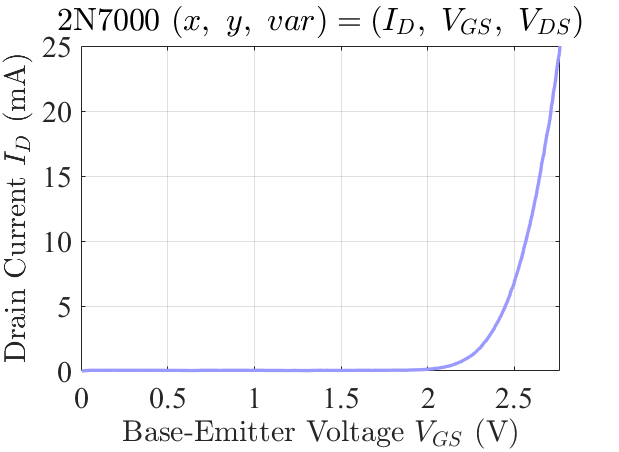

data = readmatrix("D:\aa_MyExperimentData\Raw data backup\[Experiment] 20250423_2129 NMOS 2N7000 (onsemi, KH32), current level mid (0~25mA), data num2 (Id, Vgs, Vds) (2).txt");
data = (data(1:501, :) + data(502:1002, :) + data(1003:1503, :))/3;
data_window = 10;
name = '2N7000';
gm_fit = 1;
gm_window = 10;
unit_Id = 'mA';
%MyDataProcessor_BJT_Data23_IcVbeVce_IbVbeVce_gm_rpi_BetaVbeVce
%MyDataProcessor_MOS_Data2_IdVgsVds_gmVgsVds_gmIdVds(data, data_window, name, gm_fit, gm_window, unit_Id);

% 由函数 MyDataProcessor_BJT_Data23_IcVbeVce_IbVbeVce_gm_rpi_BetaVbeVce 修改而来，有一些默认参数
unit_Ib = 'A';
% 其它默认参数：
unit_Vgs = 'V';
unit_Vds = 'V';
%{
1 (CH2) 2 (CH1)   3      4     5
Vds (V)	Id (A)	  Vgs	 Vrd   Vrg

原参考函数 Input format:
1 (CH2) 2 (CH1)   3      4     5        6
Vbe (V)	Ic (A)	  -	     -	Vrc (V)     -
  x       y       -      -     var      -
%}

%%
% 依据 Vrd (Vds) 对数据分组
leg_Vrc = unique(round(data(:, 4), 5));   % 提取 Vrc 字符串
length_Vce = length(leg_Vrc);    % 获取 Ib 总组数
Index = zeros(length_Vce, 2);    % 左起始, 右终止
for i = 1:length_Vce
    Index(i, 1) = find(  round(data(:, 4), 4) == round(leg_Vrc(i), 4)  , 1, 'first' );
    % 找到第一个; 保留 4 位小数进行判断, 避免浮点不等
    Index(i, 2) = find(  round(data(:, 4), 4) == round(leg_Vrc(i), 4)   , 1, 'last' );
    % 找到最后一个
end

% 滤波之前先获得 Beta 数据
%data_Beta = data;
%data_Beta(:, 2) = data(:, 2)./data_Ib(:, 2);

% 数据 (分组) 滤波, 不影响数据 size
if 1
    windowSize = data_window;  % 窗口大小
    b = (1/windowSize) * ones(1, windowSize);  % 滤波器系数
    a = 1;
    for i = 1:length_Vce
        data(Index(i, 1):Index(i, 2), [1 2]) = filter(b, a, data(Index(i, 1):Index(i, 2), [1 2]));  % 滤波
    end
end

%% 需要下面几个物理量的 (展示) 单位
%unit_Ic = 'mA';
%unit_Vbe = 'mV';
%unit_Vce = 'V';
%Name = 'xxxxxxx';

%amplification_Ic = 0;   % 系数初始化
switch unit_Id
    case 'A'
        amplification_Ic = 1;
    case 'mA'
        amplification_Ic = 1e3;
    case 'uA'
        amplification_Ic = 1e6;
end

switch unit_Ib
    case 'A'
        amplification_Ib = 1;
    case 'mA'
        amplification_Ib = 1e3;
    case 'uA'
        amplification_Ib = 1e6;
end

switch unit_Vgs
    case 'V'
        amplification_Vbe = 1;
    case 'mV'
        amplification_Vbe = 1e3;
    case 'uV'
        amplification_Vbe = 1e6;
end

switch unit_Vds
    case 'V'
        amplification_Vce = 1;
    case 'mV'
        amplification_Vce = 1e3;
    case 'uV'
        amplification_Vce = 1e6;
end

%%
%%%%%%%%% (Ic, Vbe, Vce) 图片代码
% 数据处理
Ic =  data(:, 2)*amplification_Ic;   % Vbe 单位转化
Vbe = data(:, 3)*amplification_Vbe;   % Vbe 单位转化
Vce = data(:, 4)*amplification_Vce;   % Vce 单位转化
leg_Vce = unique(data(:, 4))*amplification_Vce;   % 提取 Vrc 字符串

% 作图
    c = MyGet_colors_nok;
    for i = 1:length_Vce
        if i == 1
            stc.(['num', (num2str(i))]) = MyPlot(  Vbe( Index(i, 1):Index(i, 2))', Ic(Index(i, 1):Index(i, 2))'  );
            stc.(['num', (num2str(i))]).plot.Color = c{i};
        else
            stc.(['num', (num2str(i))]) = MyPlot_ax(stc.num1.axes,  Vbe( Index(i, 1):Index(i, 2))', Ic(Index(i, 1):Index(i, 2))'  );
            stc.(['num', (num2str(i))]).plot.plot_1.Color = c{i};
        end
    end
% 调整图像属性
    %stc.num1.axes.XLim(1) = 0 - stc.num1.axes.XLim(2)*0.001;
    %stc.num1.axes.YLim(1) = 0 - stc.num1.axes.YLim(2)*0.01;
    %stc.num1.axes.XLim(1) = 0;
    stc.num1.axes.YLim(1) = 0;
    str = "$V_{DS} = $ " + num2str(leg_Vce) + ' ' + unit_Vds;
    stc.num1.leg.String = str;
    stc.num1.leg.FontSize = 10;
    stc.num1.leg.Location = 'northwest';
    MyFigure_ChangeSize(stc.num1.fig, [700 512]);
    stc.num1.label.x.String = "Base-Emitter Voltage $V_{GS}$" + ' (' + unit_Vgs + ')';
    stc.num1.label.y.String = "Drain Current $I_{D}$ (" + unit_Id + ')';
    stc.num1.axes.Title.String = name + " $(x,\ y,\ var) = (I_{D},\ V_{GS},\ V_{DS})$";
    stc.num1.axes.Title.Interpreter = 'latex';
    stc.num1.axes.XLim(1) = 0;
    stc.num1.axes.YLim(1) = min(min(Ic), 0);

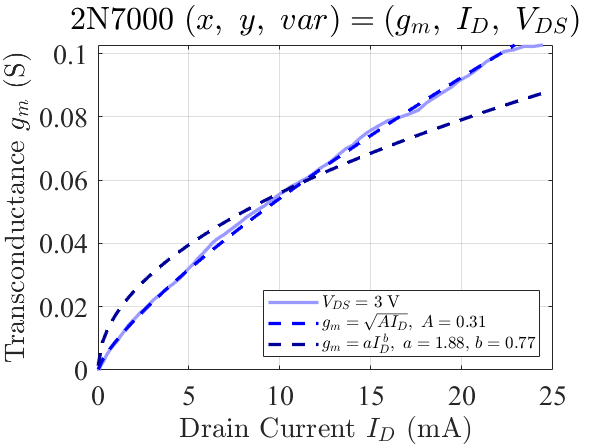

    %stc.num1.axes.YScale = 'log';
    stc_Id_Vgs_Vds = stc;
%%%%%%%%%

%% 
%%%%
if gm_fit == 1
    % 计算 (gm, Vbe, Vce) 和 (gm, Ic, Vce)
    % 计算前后建议进行滤波, 且计算时需分组
    gm = zeros(Index(1, 2) - 1, length_Vce);
    for i = 1:length_Vce
        % 注意 Ic 和 Vbe 的单位
        gm(:, i) = diff(data(Index(i, 1):Index(i, 2), 2))./diff(data(Index(i, 1):Index(i, 2), 3));
    end
    gm = MyFilter_mean(gm, gm_window);
    % 计算后的 gm 滤波:
    if 1
        gm_filted = MyFilter_mean(gm, 8);
        gm_filted = MyFilter_mean(0.6*gm + 0.4*gm_filted, 8);
        gm = MyFilter_mean(0.6*gm + 0.4*gm_filted, 5);
    end
    
    % 拟合 Vt (用 Vce 最大的一组数据来拟合)
    %length_onecolumn = size(gm, 1);
    % 提取最后一组数据进行拟合
    % 这里的 gm 是已经分好组了 (每一列是一组)
    Y_gm = gm(:, end); 
    X_Ic = Ic(  Index(end, 1):(Index(end, 2)-1)  )/amplification_Ic;    % 注意 Ic 的单位
    [fit_sqrt, ~, ~] = MyFit_sqrt(X_Ic', Y_gm', 0);    % 进行拟合 gm = sqrt(2*mu_n*C_ox*W_L*I_D) = sqrt(A*I_D)
    [fit_power, ~, ~] = MyFit_power(X_Ic', Y_gm', 0);    % 进行拟合 gm = a*Id^b

num_curve = length_Vce;


%%
%%%%%%%%%%%%%%%%% 作图 (gm, Ic, Vce)
% 作图
    c = MyGet_colors_nok;
    for i = 1:length_Vce
        if i == 1
            stc.(['num', (num2str(i))]) = MyPlot(  Ic( Index(i, 1):(Index(i, 2)-1) )', gm(:, i)' );
            stc.(['num', (num2str(i))]).plot.Color = c{i};
        else
            stc.(['num', (num2str(i))]) = MyPlot_ax(stc.num1.axes, Ic( Index(i, 1):(Index(i, 2)-1) )', gm(:, i)' );
            stc.(['num', (num2str(i))]).plot.plot_1.Color = c{i};
        end
    end
    % 获取 Id 范围, 作出 sqrt 拟合的 gm-Id 曲线 (以及幂函数拟合的曲线)
        Ic_range = stc.num1.axes.XLim/amplification_Ic;  % unit: A 
        tv_x = linspace(Ic_range(1), Ic_range(2), 100);  % unit: A 
        % 提取原本的纵坐标 gm 范围, 使视图更清晰
        gm_range = stc.num1.axes.YLim;
        % 作 26mV 曲线
        stc.(('gm_26mVcurve')) = MyPlot_ax(stc.num1.axes, tv_x*amplification_Ic, fit_power(tv_x)');
        i = i+1;
        stc.(('gm_26mVcurve')).plot.plot_1.Color = c{i};
        stc.gm_26mVcurve.plot.plot_1.LineStyle = '--';
        stc.num1.axes.YLim = gm_range;
        % 作拟合曲线
        stc.(('gm_fitcurve')) = MyPlot_ax(stc.num1.axes, tv_x*amplification_Ic, fit_sqrt(tv_x)');
        i = i+1;
        stc.(('gm_fitcurve')).plot.plot_1.Color = c{i};
        stc.gm_fitcurve.plot.plot_1.LineStyle = '--';
        stc.num1.axes.YLim = gm_range;
% 调整图像属性
    stc.num1.axes.YLim(1) = 0;
    str = "$V_{DS} = $ " + num2str(leg_Vce) + ' ' + unit_Vds;
    %str = num2str(leg_str) + " V";
    if gm_fit == 1
        stc.num1.leg.String = [str; "$g_m = \sqrt{AI_D},\ A = $ " + num2str(fit_sqrt.A, '%.2f'); "$g_m = aI_D^{\,b},\ a = $ " + num2str(fit_power.a, '%.2f') + ', $b = $ ' + num2str(fit_power.b, '%.2f');];
    else
        stc.num1.leg.String = str;
    end
    stc.num1.leg.FontSize = 10;
    stc.num1.leg.Location = 'southeast';
    MyFigure_ChangeSize(stc.num1.fig, [700 512]);
    stc.num1.label.x.String = "Drain Current $I_{D}$ (" + unit_Id + ')';
    stc.num1.label.y.String = 'Transconductance $g_m$ (S)';
    stc.num1.axes.Title.String = name + " $(x,\ y,\ var) = (g_m,\ I_D,\ V_{DS})$";
    stc.num1.axes.Title.Interpreter = 'latex';
    stc.num1.axes.XLim(1) = 0;
    stc.num1.axes.XLim(2) = max(Ic);
    %stc.num1.axes.YLim(1) = min(gm, [], 'all');
    stc_gm_Id_Vds = stc;
    stc_gm_Id_Vds.V_T = V_T;    % return V_T, 可用于 intrisic gain
    
%%%%%%%%%%%%%%%%%

if num_curve > 1    % 当 Vds 仅有一个取值时 (仅有一条曲线), 用 YY 图替代这个图
%%
%%%%%%%%%%%%%%%%% 作图 (gm, Vbe, Vce)
% 作图
    c = MyGet_colors_nok;
    for i = 1:length_Vce
        if i == 1
            stc.(['num', (num2str(i))]) = MyPlot(  Vbe(  Index(i, 1):(Index(i, 2)-1)  )', gm(:, i)');
            stc.(['num', (num2str(i))]).plot.Color = c{i};
            %stc.(['num', (num2str(i))]).leg.String(i) = cellstr(num2str(leg_str(i, :)));
        else
            stc.(['num', (num2str(i))]) = MyPlot_ax(stc.num1.axes,  Vbe(  Index(i, 1):(Index(i, 2)-1)  )', gm(:, i)');
            stc.(['num', (num2str(i))]).plot.plot_1.Color = c{i};
            %stc.(['num', (num2str(i))]).leg.String(i) = cellstr(num2str(leg_str(i, :)));
        end
    end
% 调整图像属性
    stc.num1.axes.XLim(1) = 0;
    stc.num1.axes.YLim(1) = 0;
    str = "$V_{DS} = $ " + num2str(leg_Vce) + ' ' + unit_Vds;
    stc.num1.leg.String = str;
    stc.num1.leg.FontSize = 10;
    stc.num1.leg.Location = 'northwest';
    MyFigure_ChangeSize(stc.num1.fig, [700 512]);
    stc.num1.label.x.String = "Base-Emitter Voltage $V_{GS}$ (" + unit_Vgs + ')';
    stc.num1.label.y.String = 'Transconductance $g_m$ (S)';
    stc.num1.axes.Title.String = name + " $(x,\ y,\ var) = (g_m,\ V_{GS},\ V_{DS})$";
    stc.num1.axes.Title.Interpreter = 'latex';
    stc.num1.axes.YLim(1) = min(gm, [], 'all');
    %stc.num1.axes.YScale = 'log';
    stc_gm_Vgs_Vds = stc;
%%%%%%%%%%%%%%%%%
end

end

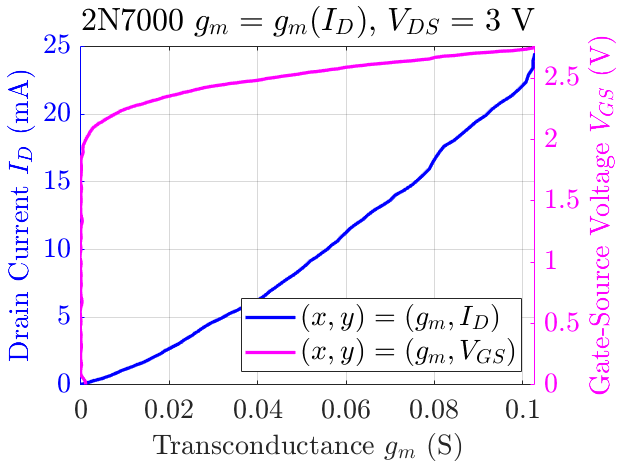


if gm_fit == 0
    stc_gm_Vgs_Vds = 0;
    stc_gm_Id_Vds = 0;
end

if num_curve == 1 
    i = 1;
    stc = MyYYPlot([gm'; gm'], [Ic( Index(i, 1):(Index(i, 2)-1) )'; Vbe( Index(i, 1):(Index(i, 2)-1) )']);
    % 调整图像属性
    yyaxis('left');
    stc.axes.YLim(1) = min(min(Ic), 0);
    stc.axes.YLim(2) = max(Ic);
    yyaxis('right');
    stc.axes.YLim(1) = min(min(Vbe), 0);
    stc.axes.YLim(2) = max(Vbe);

    str = "$V_{DS} =$ " + num2str(leg_Vce) + ' ' + unit_Vds;
    stc.leg.String = ["$(x,y) = (g_m, I_D)$"; "$(x,y) = (g_m, V_{GS})$"];
    stc.leg.Location = 'southeast';
    stc.axes.Title.String = name + " $g_m = g_m(I_D)$, " + str;
    stc.label.x.String = 'Transconductance $g_m$ (S)';
    stc.label.y_left.String = "Drain Current $I_{D}$ (" + unit_Id + ')';
    stc.label.y_right.String = "Gate-Source Voltage $V_{GS}$ (" + unit_Vgs + ')';
    stc_gm_IdVgs_yyplot = stc;
end